# Example use of functions listed in the Standard operating procedure for metabolic reconstruction

**Author(s): Ines Thiele LCSB, University of Luxembourg.**

**Reviewer(s): **

## **INTRODUCTION**

This tutorial has been adapted and expanded from [1].

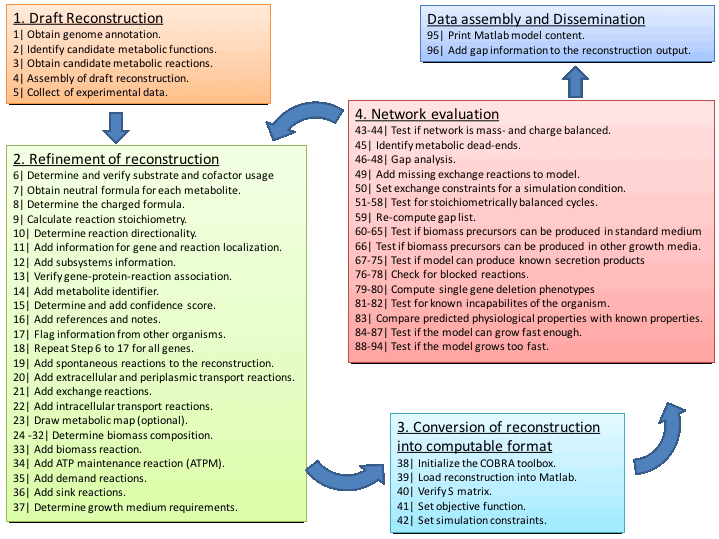

*In the following, we will illustrate example input for the COBRA Toolbox functions used in Step 38 to 96 using the E. coli core reconstruction [2] as the model of choice. When Matlab/Toolbox commands are following by a ‘;’ the output is not printed. Omitting the ‘;’ invokes printing of the variable content. *

## EQUIPMENT SETUP

**38.  Initialize the COBRA Toolbox.**

%initCobraToolbox

**Setting the linear programming (LP) solver, for example, ‘glkp’:**

changeCobraSolver ('glpk', 'all', 1);

 > Solver for LPproblems has been set to glpk.
 > Solver for MILPproblems has been set to glpk.
 > Solver glpk not supported for problems of type MIQP. Currently used: gurobi 
 > Solver glpk not supported for problems of type NLP. Currently used: matlab 
 > Solver glpk not supported for problems of type QP. Currently used: qpng 


This tutorial can be run with `'glpk``'` package as linear programming solver, which does not require additional instalation and configuration. However, for the analysis of large models, such as Recon 3, it is not recommended to use `'glpk``'` but rather industrial strenght solvers, such as the `'gurobi'` package. For detail information, refer to the solver instalation guide: [https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md)

warning off MATLAB:subscripting:noSubscriptsSpecified

## PROCEDURE

**39.  Load reconstruction into Matlab**. 

The reaction list is contained by the file 'Ecoli_core_model.mat':

load('Ecoli_core_model.mat');

The reconstruction is contained in the resulting model structure: modelEcore. 

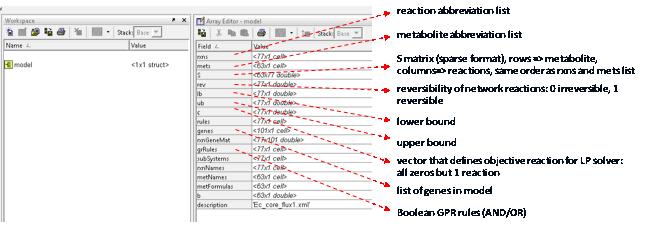

See Figure above for the data contained in the different structure fields. We will use this model structure for all consequent computation if not noted differently.

The content of the structure can be assessed as follows:

- You wish to see the abbreviation of the 8th metabolite in the model:

modelEcore.mets{8}

ans = acald[c]

- You wish to see the abbreviation of the 1st reaction in the model:

modelEcore.rxns{1}

ans = ACALD

- You wish to see the entry of the stoichiometric matrix of the 1st reaction (column) and 8th metabolite (row):

modelEcore.S(8,1)

ans =    (1,1)       -1


- Print the reaction formula:

printRxnFormula(modelEcore,modelEcore.rxns(1))

ACALD	acald[c] + coa[c] + nad[c] 	<=>	accoa[c] + h[c] + nadh[c] 


ans =     'acald[c] + coa[c] + nad[c]  <=> accoa[c] + h[c] + nadh[c] '


- You want to change the lower bound (lb) of the 5th reaction to 10 mmol/gDW/h (without using any COBRA Toolbox functions):

modelEcore.lb(5) = 10

modelEcore =                 rxns: {95×1 cell}
                mets: {72×1 cell}
                   S: [72×95 double]
                 rev: [95×1 double]
                  lb: [95×1 double]
                  ub: [95×1 double]
                   c: [95×1 double]
           metCharge: [72×1 int32]
               rules: {95×1 cell}
               genes: {137×1 cell}
          rxnGeneMat: [95×137 double]
             grRules: {95×1 cell}
          subSystems: {95×1 cell}
    confidenceScores: {95×1 cell}
           citations: {95×1 cell}
           ecNumbers: {95×1 cell}
            comments: {95×1 cell}
            rxnNames: {95×1 cell}
            metNames: {72×1 cell}
         metFormulas: {72×1 cell}
          metCHEBIID: {72×1 cell}
           metKeggID: {72×1 cell}
        metPubChemID: {72×1 cell}
      metInchiString: {72×1 cell}
                   b: [72×1 double]
         description: 'ecoli_core_model'


- You want to add a field to the model structure. 

            A note: 

modelEcore.newField = 'ABC – a note'

modelEcore =                 rxns: {95×1 cell}
                mets: {72×1 cell}
                   S: [72×95 double]
                 rev: [95×1 double]
                  lb: [95×1 double]
                  ub: [95×1 double]
                   c: [95×1 double]
           metCharge: [72×1 int32]
               rules: {95×1 cell}
               genes: {137×1 cell}
          rxnGeneMat: [95×137 double]
             grRules: {95×1 cell}
          subSystems: {95×1 cell}
    confidenceScores: {95×1 cell}
           citations: {95×1 cell}
           ecNumbers: {95×1 cell}
            comments: {95×1 cell}
            rxnNames: {95×1 cell}
            metNames: {72×1 cell}
         metFormulas: {72×1 cell}
          metCHEBIID: {72×1 cell}
           metKeggID: {72×1 cell}
        metPubChemID: {72×1 cell}
      metInchiString: {72×1 cell}
                   b: [72×1 double]
         description: 'ecoli_core_model'
            newField: 'ABC – a note'


            An array B = [1 2 3]

B = [1 2 3];
modelEcore.newField = B

modelEcore =                 rxns: {95×1 cell}
                mets: {72×1 cell}
                   S: [72×95 double]
                 rev: [95×1 double]
                  lb: [95×1 double]
                  ub: [95×1 double]
                   c: [95×1 double]
           metCharge: [72×1 int32]
               rules: {95×1 cell}
               genes: {137×1 cell}
          rxnGeneMat: [95×137 double]
             grRules: {95×1 cell}
          subSystems: {95×1 cell}
    confidenceScores: {95×1 cell}
           citations: {95×1 cell}
           ecNumbers: {95×1 cell}
            comments: {95×1 cell}
            rxnNames: {95×1 cell}
            metNames: {72×1 cell}
         metFormulas: {72×1 cell}
          metCHEBIID: {72×1 cell}
           metKeggID: {72×1 cell}
        metPubChemID: {72×1 cell}
      metInchiString: {72×1 cell}
                   b: [72×1 double]
         description: 'ecoli_core_model'
            newField: [1 2 3]


- Create a list of strings:

ListStrings = {'A' 'B' 'C'}

ListStrings =     'A'    'B'    'C'


- Create a list of numbers: 

ListNumbers = [1 2 3]

ListNumbers =      1     2     3


- Transpose a list:

ListTranspose = ListNumbers'

ListTranspose =      1
     2
     3


- Find the index of a reaction, e.g., ‘ATPM', in the model 

RxnNumber = strmatch('ATPM', modelEcore.rxns,'exact')

RxnNumber = 11

**40.  Verify S matrix.**

- Here, all non-zero entries in the S matrix are visualized. Remember that the rows correspond to the metabolites and to columns to the reactions in the model. The number of non-zero entries is given below the spy image. 

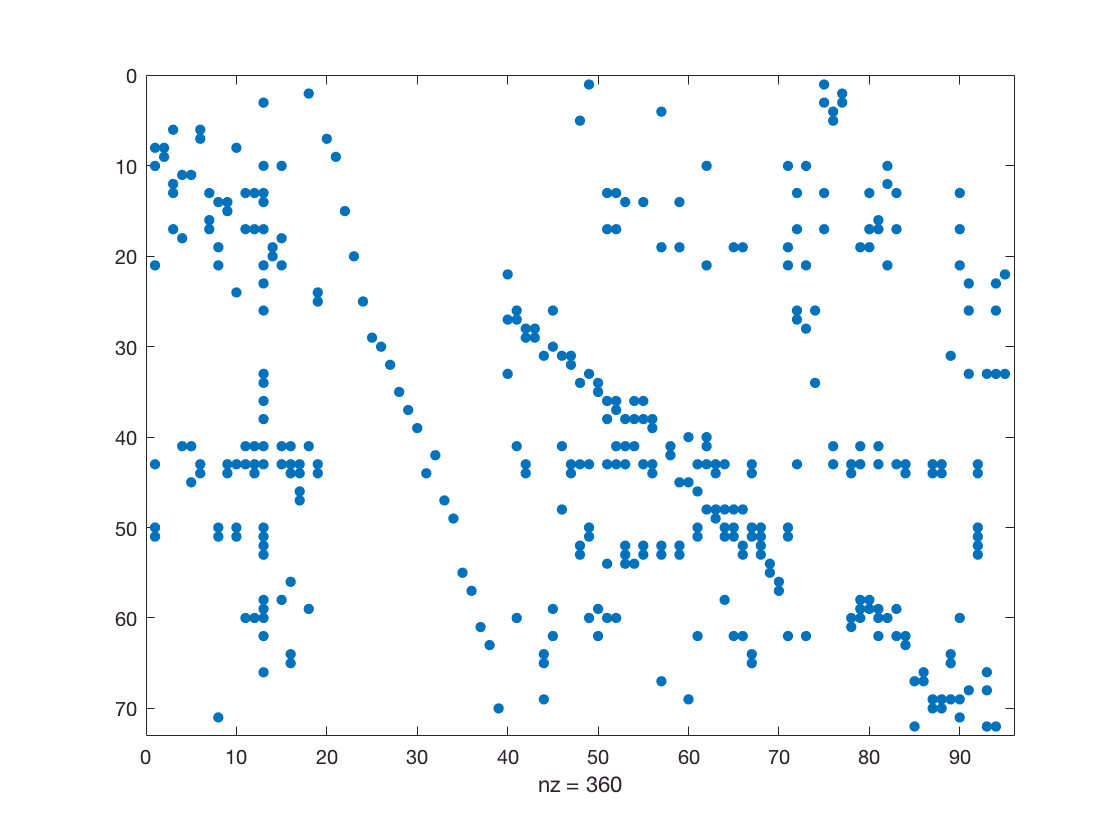

spy(modelEcore.S)

- To put this number into perspective, we can calculate the percentage of non-zero entries of S:

[a,b] = size(modelEcore.S);
nz = nnz(modelEcore.S);
Perc_nz = nz*100/(a*b)

Perc_nz = 5.2632

- Many large  scale models have less than 1% of non-zero entries in the S matrix.

- Looking at the S matrix is a quick way to see whether there is something obviously wrong with the model and the S matrix.

- Here are two examples of S matrices:

E. coli - AF1260 [3]

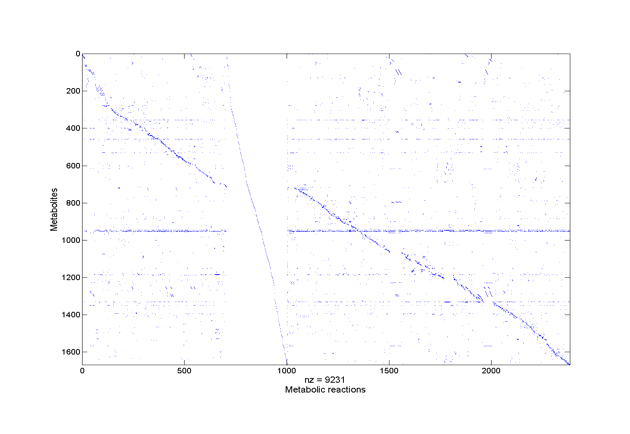

*Geobacter** sulfurreducans [4]*

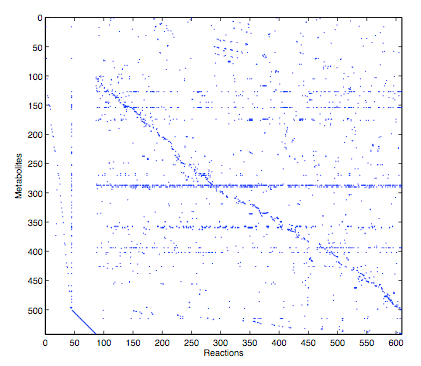

Consider to also use the tutorial on 'Numerical properties of a reconstruction' to investigate the propeties of the S matrix.

**41.  Set objective function**. We will set the biomass reaction (Biomass_Ecoli_core_w_GAM) of the *E. coli*core model as objective function: 

modelEcore = changeObjective(modelEcore, 'Biomass_Ecoli_core_w_GAM');

- If you wish to check wish reaction(s) make up the objective function and its components, use the following function:

[objectiveAbbr] = checkObjective(modelEcore)

summaryT =     Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

     -1.496        3pg[c]         3       Biomass_Ecoli_core_w_GAM    13   
    -3.7478        accoa[c]      10       Biomass_Ecoli_core_w_GAM    13   
      59.81        adp[c]        13       Biomass_Ecoli_core_w_GAM    13   
     4.1182        akg[c]        14       Biomass_Ecoli_core_w_GAM    13   
     -59.81        atp[c]        17       Biomass_Ecoli_core_w_GAM    13   
     3.7478        coa[c]        21       Biomass_Ecoli_core_w_GAM    13   
     -0.361        e4p[c]        23       Biomass_Ecoli_core_w_GAM    13   
    -0.0709        f6p[c]        26       Biomass_Ecoli_core_w_GAM    13   
     -0.129        g3p[c]        33       Biomass_Ecoli_co

objectiveAbbr =     'Biomass_Ecoli_core_w_GAM'


**42.  Set simulation constraints**. 

- A first step when using and debugging a model should be to identify, which constraints have been applied.

printConstraints(modelEcore, -1000,1000)

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
EX_glc(e)	-1.000000e+01
maxConstraints:


- As you can see, only three reactions are constrained in this model. The glucose exchange reaction (EX_glc(e)), the aconitase reaction (ACONTb) and the ATP non-growth associated maintenance reaction (ATPM). Note that in all three cases, a lower bound has been set only but no upper bound.

- Note also that this function returns only those constraints that are greater than -1000 but smaller than 1000.

- To know, which medium constraints are applied to the model, we can use the following function:

printUptakeBound(modelEcore);

EX_co2(e)	-1000	
EX_glc(e)	-10	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	


- As you can see, the model is set to a minimal medium with the presence of oxygen.

- Let’s assume that you would like to set the lower bound of the ATP maintenance reaction (‘ATPM’) to 8.39 mmol/gDW/h:

modelEcore = changeRxnBounds(modelEcore,'ATPM',8.39,'l');

            and the upper bound of the ‘ATPM’ reaction to 8.39 mmol/gDW/h: 

modelEcore = changeRxnBounds(modelEcore,'ATPM',8.39,'u');

- The same effect could have been achieved using: 

modelEcore = changeRxnBounds(modelEcore,'ATPM',8.39,'b');

- Let’s assume that you would like to set the lower bound of the ‘ATPM’ reaction to 8.39 mmol/gDW/h and the ATP synthetase (‘ATPS4r’) to an upper bound of 100 mmol/gDW/h:

modelEcore = changeRxnBounds(modelEcore,'ATPM' ,8.39,'l' );
modelEcore = changeRxnBounds(modelEcore, 'ATPS4r',100, 'u');

- The set constraints can be checked using the following function:

printConstraints(modelEcore, -1000,1000)

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
EX_glc(e)	-1.000000e+01
maxConstraints:
ATPM	8.390000e+00
ATPS4r	1.000000e+02


Note that the ‘MinInf’ and ‘MaxInf’ were set to -1000 and 1000, respectively, as this numbers represent infinity in the E. coli core model. Other models may have different infinities.

**43.  Test if network is mass- and charge balanced.**

- Check for entire network:

[massImbalance, imBalancedMass, imBalancedCharge, imBalancedRxnBool, Elements, missingFormulaeBool, balancedMetBool] = checkMassChargeBalance(modelEcore) 

massImbalance =    (1,1)      NaN
   (2,1)      NaN
   (3,1)      NaN
   (4,1)      NaN
   (5,1)      NaN
   (6,1)      NaN
   (7,1)      NaN
   (8,1)      NaN
   (9,1)      NaN
  (10,1)      NaN
  (11,1)      NaN
  (12,1)      NaN
  (13,1)      NaN
  (14,1)      NaN
  (15,1)      NaN
  (16,1)      NaN
  (17,1)      NaN
  (18,1)      NaN
  (19,1)      NaN
  (20,1)      NaN
  (21,1)      NaN
  (22,1)      NaN
  (23,1)      NaN
  (24,1)      NaN
  (25,1)      NaN
  (26,1)      NaN
  (27,1)      NaN
  (28,1)      NaN
  (29,1)      NaN
  (30,1)      NaN
  (31,1)      NaN
  (32,1)      NaN
  (33,1)      NaN
  (34,1)      NaN
  (35,1)      NaN
  (36,1)      NaN
  (37,1)      NaN
  (38,1)      NaN
  (39,1)      NaN
  (40,1)      NaN
  (41,1)      NaN
  (42,1)      NaN
  (43,1)      NaN
  (44,1)      NaN
  (45,1)      NaN
  (46,1)      NaN
  (47,1)      NaN
  (48,1)      NaN
  (49,1)      NaN
  (50,1)      NaN
  (51,1)      NaN
  (52,1)      NaN
  (53,1)      NaN
  (54,1)      NaN
  (55,1)    

imBalancedMass =     'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'
    'NaN'


imBalancedCharge =    NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN
   NaN


imBalancedRxnBool =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


Elements =     'H'    'C'    'O'    'P'    'S'    'N'    'Mg'    'X'    'Fe'    'Zn'    'Co'    'R'    'Ca'    'Y'    'I'    'Na'    'Cl'    'K'    'R'    'FULLR'


missingFormulaeBool =    1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


balancedMetBool =    0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


**44.  Identify metabolic dead-ends**

- Detect deadend metabolites

outputMets = detectDeadEnds(modelEcore)

outputMets =     30
    32
    37
    49


- print the corresponding metabolite names

DeadEnds = modelEcore.mets(outputMets)

DeadEnds =     'fru[e]'
    'fum[e]'
    'gln-L[e]'
    'mal-L[e]'


- These metabolites are only produced or consumed in the network and the associated reactions are blocked reactions.

- Identify associated reactions:

[rxnList, rxnFormulaList] = findRxnsFromMets(modelEcore, DeadEnds)

rxnList =     'EX_fru(e)'
    'EX_fum(e)'
    'EX_gln_L(e)'
    'EX_mal_L(e)'
    'FRUpts2'
    'FUMt2_2'
    'GLNabc'
    'MALt2_2'


rxnFormulaList =     'fru[e]  -> '
    'fum[e]  -> '
    'gln-L[e]  -> '
    'mal-L[e]  -> '
    'fru[e] + pep[c]  -> f6p[c] + pyr[c] '
    'fum[e] + 2 h[e]  -> fum[c] + 2 h[c] '
    'atp[c] + gln-L[e] + h2o[c]  -> adp[c] + gln-L[c] + h[c] + pi[c] '
    '2 h[e] + mal-L[e]  -> 2 h[c] + mal-L[c] '


- As you can see, these metabolites have each two reactions associated. Why are they then detected as deadend metabolites?

- Let's have a look at the lower and upper bounds of these reactions:

modelEcore.lb(find(ismember(modelEcore.rxns,rxnList)))

ans =      0
     0
     0
     0
     0
     0
     0
     0


modelEcore.ub(find(ismember(modelEcore.rxns,rxnList)))

ans =         1000
        1000
        1000
        1000
        1000
        1000
        1000
        1000


- In this particular case, these four metabolites are deadend metabolites as the associated exchange reactions are set to lb=0 (i.e., no uptake is permitted). As we are interested in dead-end metabolites that are generally only consumed or produced by the network, irrespective of the applied constraints, we will set the lower bound of all exchange reaction to -1000 and the upper bound to 1000.

modelEcore_New = modelEcore;
modelEcore_New.lb(strmatch('EX_',modelEcore_New.rxns)) = -1000;
modelEcore_New.ub(strmatch('EX_',modelEcore_New.rxns)) = 1000;

- Now we repeat the identification of deadend metabolites:

outputMets = detectDeadEnds(modelEcore_New)


outputMets =

  0×1 empty double column vector



DeadEnds = modelEcore_New.mets(outputMets)


DeadEnds =

  0×1 empty cell array



[rxnList, rxnFormulaList] = findRxnsFromMets(modelEcore_New, DeadEnds)


rxnList =

  0×1 empty cell array




rxnFormulaList =

  0×0 empty cell array



- And indeed no deadend metabolites remain. This example also illustrates how such issues can be fixed - one option is to revert the directionality of the associated reactions. Note that changing the directionality must be carefully evaluated in each case, to ensure that the resulting model is biologically accurate. For instance, changing the directionality of the 'FRUpts_2' reaction would have not been biologically meaningful, as the Phosphotransferase system is known to be unidirectional under physiologically relevant conditions.

## ***Test for stoic******hiom******etrically balanced cycles (SBCs).***

**51.**  **Test for Type III pathways.**Therefore, use the following function: TestForTypeIIIPathways. The indices of the exchange reactions are given by [24:43], which creates a list from 23 to 43. If the exchange reactions are distributed across the network, a list of all indices can be given as input (e.g., [1 2 5]). The output filename can be specified with ‘test’, it receives automatically the extension ‘.expa’. The filename is optional, the default name is: 'ModelTestTypeIII'

testForTypeIIIPathways(modelEcore,strmatch('EX_',modelEcore.rxns),'test');

No Type III pathways can be found in model.rm: test_myT3_Sprs.txttest_myT3.txttest_myRxnMet.txt: No such file or directory
/bin/bash: del: command not found


*This error message is returned from X3.exe since there are no SBCs in the E. coli core network.*

## ***Test if biomass precursors can be produced in standard medium***

**60.**  Obtain the list of biomass components:

BiomassComponents = modelEcore.mets(find(modelEcore.S(:,strmatch('Biomass',modelEcore.rxns))))

BiomassComponents =     '3pg[c]'
    'accoa[c]'
    'adp[c]'
    'akg[c]'
    'atp[c]'
    'coa[c]'
    'e4p[c]'
    'f6p[c]'
    'g3p[c]'
    'g6p[c]'
    'gln-L[c]'
    'glu-L[c]'
    'h2o[c]'
    'h[c]'
    'nad[c]'
    'nadh[c]'
    'nadp[c]'
    'nadph[c]'
    'oaa[c]'
    'pep[c]'
    'pi[c]'
    'pyr[c]'
    'r5p[c]'


**61.**  Add demand function for each biomass precursor:

[modelEcore_NEW ,rxnNames] = addDemandReaction(modelEcore, BiomassComponents);

DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_adp[c]	adp[c] 	->	
DM_akg[c]	akg[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_coa[c]	coa[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_h[c]	h[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadh[c]	nadh[c] 	->	
DM_nadp[c]	nadp[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pi[c]	pi[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


*For each biomass component i, perform the following test:*

for i = 1 : length(BiomassComponents)

**62.**  Change objective function to the demand function:

    modelEcore_NEW = changeObjective(modelEcore_NEW, rxnNames(i));

ans =     '3pg[c]'      [    10.0000]
    'accoa[c]'    [ 1.7764e-15]
    'adp[c]'      [-3.5527e-15]
    'akg[c]'      [    10.0000]
    'atp[c]'      [          0]
    'coa[c]'      [          0]
    'e4p[c]'      [     7.5000]
    'f6p[c]'      [          5]
    'g3p[c]'      [    10.0000]
    'g6p[c]'      [     5.0000]
    'gln-L[c]'    [    10.0000]
    'glu-L[c]'    [    10.0000]
    'h2o[c]'      [       1000]
    'h[c]'        [       1000]
    'nad[c]'      [-7.1054e-15]
    'nadh[c]'     [ 7.1054e-15]
    'nadp[c]'     [          0]
    'nadph[c]'    [          0]
    'oaa[c]'      [    10.0000]
    'pep[c]'      [    10.0000]
    'pi[c]'       [       1000]
    'pyr[c]'      [    10.0000]
    'r5p[c]'      [     6.0000]


**63.**  Maximize (‘max’) for new objective function (Demand function)

    FBAsolution = optimizeCbModel (modelEcore_NEW,'max');

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
EX_glc(e)	-1.000000e+01
maxConstraints:
ATPM	8.390000e+00
ATPS4r	1.000000e+02


- FBAsolution is a structure containing the result of the optimization. FBAsolution.f gives the maximal value of the objective reaction (i.e., 'DM_pep[c]'), which is greater than 0 mmol/gDW/h. This means that our *E. coli*core model can produce pep[c]. 

- Store each solution in a vector:

    BiomassComponentsValue(i,1) = FBAsolution.f;
end

summaryT =     Coefficient    Metabolite    metID            Reaction            RxnID
    ___________    __________    _____    ________________________    _____

     -1.496        3pg[c]         3       Biomass_Ecoli_core_w_GAM    13   
    -3.7478        accoa[c]      10       Biomass_Ecoli_core_w_GAM    13   
      59.81        adp[c]        13       Biomass_Ecoli_core_w_GAM    13   
     4.1182        akg[c]        14       Biomass_Ecoli_core_w_GAM    13   
     -59.81        atp[c]        17       Biomass_Ecoli_core_w_GAM    13   
     3.7478        coa[c]        21       Biomass_Ecoli_core_w_GAM    13   
     -0.361        e4p[c]        23       Biomass_Ecoli_core_w_GAM    13   
    -0.0709        f6p[c]        26       Biomass_Ecoli_core_w_GAM    13   
     -0.129        g3p[c]        33       Biomass_Ecoli_co

objectiveAbbr =     'Biomass_Ecoli_core_w_GAM'


- Print each BiomassComponent and the corresponding value:

[BiomassComponents  num2cell(BiomassComponentsValue)]

BiomassComponentsPos =     'adp[c]'
    'akg[c]'
    'coa[c]'
    'h[c]'
    'nadh[c]'
    'nadp[c]'
    'pi[c]'


- As we can see, not all biomass components (or rather their corresponding demand reaction) can have a non-zero flux. Why is that?

- Just to remember us, the model constraints are:

printConstraints(modelEcore_NEW, -1000,1000)

BiomassComponentsNeg =     '3pg[c]'
    'accoa[c]'
    'atp[c]'
    'e4p[c]'
    'f6p[c]'
    'g3p[c]'
    'g6p[c]'
    'gln-L[c]'
    'glu-L[c]'
    'h2o[c]'
    'nad[c]'
    'nadph[c]'
    'oaa[c]'
    'pep[c]'
    'pyr[c]'
    'r5p[c]'


- Note that only those constraints will be printed that are smaller greater than -1000 and smaller than 1000.

- Let's revisit how the biomass reaction is formulated in this model:

modelEcore = changeObjective(modelEcore,modelEcore.rxns(strmatch('Biomass',modelEcore.rxns)));

sink_adp[c]	adp[c] 	<=>	
sink_akg[c]	akg[c] 	<=>	
sink_coa[c]	coa[c] 	<=>	
sink_h[c]	h[c] 	<=>	
sink_nadh[c]	nadh[c] 	<=>	
sink_nadp[c]	nadp[c] 	<=>	
sink_pi[c]	pi[c] 	<=>	


[objectiveAbbr] = checkObjective(modelEcore)

DM_3pg[c]	3pg[c] 	->	
DM_accoa[c]	accoa[c] 	->	
DM_atp[c]	atp[c] 	->	
DM_e4p[c]	e4p[c] 	->	
DM_f6p[c]	f6p[c] 	->	
DM_g3p[c]	g3p[c] 	->	
DM_g6p[c]	g6p[c] 	->	
DM_gln-L[c]	gln-L[c] 	->	
DM_glu-L[c]	glu-L[c] 	->	
DM_h2o[c]	h2o[c] 	->	
DM_nad[c]	nad[c] 	->	
DM_nadph[c]	nadph[c] 	->	
DM_oaa[c]	oaa[c] 	->	
DM_pep[c]	pep[c] 	->	
DM_pyr[c]	pyr[c] 	->	
DM_r5p[c]	r5p[c] 	->	


-  As you can see, there are numerous metabolites that have a positive coefficient in the biomass equation, meaning that they are produced by the biomass reaction and thus we need to test whether these metabolites can be removed, rather than produced by the model. Hence, we need to add sink reactions (rather than demand reactions) and minimize them:

- Let's get all biomass components with a positive coefficient in the biomass reaction:

BiomassComponentsPos = modelEcore.mets(find(modelEcore.S(:,strmatch('Biomass',modelEcore.rxns))>0))
BiomassComponentsNeg = modelEcore.mets(find(modelEcore.S(:,strmatch('Biomass',modelEcore.rxns))<0))

[modelEcore_NEW] = addSinkReactions(modelEcore, BiomassComponentsPos);

ans =     'adp[c]'     [    -1000]
    'akg[c]'     [    -1000]
    'coa[c]'     [-663.3333]
    'h[c]'       [    -1000]
    'nadh[c]'    [    -1000]
    'nadp[c]'    [    -1000]
    'pi[c]'      [    -1000]


[modelEcore_NEW ,rxnNames] = addDemandReaction(modelEcore_NEW, BiomassComponentsNeg);

- Note that we added both the sink and the demand reactions to the model simultanously. The reason for this is that metabolites such as coa and accoa or nadh and nad are not produced or consumed in this model but only recycled. Hence, for obtaining a non-zero flux for any of the associated sink or demand reactions one needs to add the reaction pair. In larger networks (than the E. coli core model) this will be less of a problem as they capture the biosynthetic pathways for these metabolites.

Now lets repeat the analysis: Note that we minimize the objective

for i = 1 : length(BiomassComponentsPos)
    modelEcore_NEW = changeObjective(modelEcore_NEW, strcat('sink_',BiomassComponentsPos(i)));
    FBAsolution = optimizeCbModel (modelEcore_NEW,'min');
    BiomassComponentsValuePos(i,1) = FBAsolution.f;
end
[BiomassComponentsPos  num2cell(BiomassComponentsValuePos)]

ans =     '3pg[c]'      [  555.8050]
    'accoa[c]'    [  663.3333]
    'atp[c]'      [1.0000e+03]
    'e4p[c]'      [  280.4025]
    'f6p[c]'      [  186.9350]
    'g3p[c]'      [  370.5367]
    'g6p[c]'      [  186.9350]
    'gln-L[c]'    [       500]
    'glu-L[c]'    [1.0000e+03]
    'h2o[c]'      [      1000]
    'nad[c]'      [1.0000e+03]
    'nadph[c]'    [      1000]
    'oaa[c]'      [  990.1464]
    'pep[c]'      [  555.8050]
    'pyr[c]'      [  992.5000]
    'r5p[c]'      [  224.3220]


- All these metabolites can be removed by the model.

- We repeat the same analysis for all negative biomass components.

Now lets repeat the analysis: Note that we maximize the objective

for i = 1 : length(BiomassComponentsNeg)
    modelEcore_NEW = changeObjective(modelEcore_NEW, strcat('DM_',BiomassComponentsNeg(i)));

ans = 0.7082

    FBAsolution = optimizeCbModel (modelEcore_NEW,'max');
    BiomassComponentsValueNeg(i,1) = FBAsolution.f;

ACONTa	10	
ACONTb	10	
AKGDH	9.23588	
ATPM	8.39	
ATPS4r	28.2124	
Biomass_Ecoli_core_w_GAM	0.708235	
CO2t	-29.8607	
CS	10	
CYTBD	58.0838	
ENO	17.0578	
EX_co2(e)	29.8607	
EX_glc(e)	-10	
EX_h(e)	14.2072	
EX_h2o(e)	35.0198	
EX_nh4(e)	-3.86187	
EX_o2(e)	-29.0419	
EX_pi(e)	-2.60539	
FBA	9.29552	
FORt2	127.234	
FORti	127.234	
FUM	9.23588	
GAPD	18.1173	
GLCpts	10	
GLNS	0.181096	
GLUDy	-3.68077	
H2Ot	-35.0198	
ICDHyr	10	
MDH	9.23588	
NADH16	48.8479	
NH4t	3.86187	
O2t	29.0419	
PDH	12.6543	
PFK	9.29552	
PGI	9.85481	
PGK	-18.1173	
PGM	-17.0578	
PIt2r	2.60539	
PPC	2.02952	
PYK	4.66061	
RPE	-0.50908	
RPI	-0.50908	
SUCDi	9.23588	
SUCOAS	-9.23588	
TALA	-0.126703	
THD2	2.90759	
TKT1	-0.126703	
TKT2	-0.382376	
TPI	9.29552	


end
[BiomassComponentsNeg  num2cell(BiomassComponentsValueNeg)]

- All these biomass precursors can be produced by the model. Hence a non-zero, positive flux through the biomass reaction should be possible:

FBAsolution = optimizeCbModel(modelEcore,'max');

ans = 0.7082

FBAsolution.f

ACONTa	10	
ACONTb	10	
AKGDH	3.69917	
ATPM	8.39	
ATPS4r	31.7196	
Biomass_Ecoli_core_w_GAM	0.708235	
CO2t	-11.6696	
CS	10	
CYTBD	39.8928	
ENO	17.0578	
EX_co2(e)	11.6696	
EX_for(e)	18.191	
EX_glc(e)	-10	
EX_h(e)	32.3982	
EX_h2o(e)	16.8287	
EX_nh4(e)	-3.86187	
EX_o2(e)	-19.9464	
EX_pi(e)	-2.60539	
FBA	9.29552	
FORti	18.191	
FUM	9.23588	
GAPD	18.1173	
GLCpts	10	
GLNS	0.181096	
GLUDy	-3.68077	
H2Ot	-16.8287	
ICDHyr	4.46328	
ICL	5.53672	
MALS	5.53672	
MDH	11.2654	
ME2	3.5072	
NADH16	30.6569	
NH4t	3.86187	
O2t	19.9464	
PFK	9.29552	
PFL	18.191	
PGI	9.85481	
PGK	-18.1173	
PGM	-17.0578	
PIt2r	2.60539	
PYK	6.69013	
RPE	-0.50908	
RPI	-0.50908	
SUCDi	9.23588	
SUCOAS	-3.69917	
TALA	-0.126703	
THD2	4.93711	
TKT1	-0.126703	
TKT2	-0.382376	
TPI	9.29552	


- FBAsolution.x contains the flux value for each reaction in the network. Use:

printFluxVector(modelEcore,FBAsolution.x,'true')

-  To see which network reactions participate in the optimal solution. Keep in mind that there may be more than one optimal solution (so-called alternate optimal solutions, which have the same optimal value for the objective function but the internal flux distribution may be different) .

- Compare this solution with a sparse FBA solution, which returns an optimal flux distribution with the least number of active model reactions. Note that the underlying algorithm is an approximation to the exact sparsest solution and also that there may be alternative optimal solutions with equal numbers of active reactions.

FBAsolution = optimizeCbModel(modelEcore,'max','zero');
FBAsolution.f
printFluxVector(modelEcore,FBAsolution.x,'true')

## ***Test if model can produce known secretion products.***

**68. ** Set the constraints to the desired medium condition (e.g., minimal medium + carbon source). For changing the constraints use the following function:

modelEcore_New = changeRxnBounds(modelEcore, {'EX_glc(e)' 'EX_o2(e)'},[-10 -18.5],'l');

- If the model shall be required to grow in addition to producing the by-product, set the lower bound (boundType = ‘l’) of the biomass reaction (‘rxnNameList ‘) to the corresponding value (‘value’). 

modelEcore_New = changeRxnBounds(modelEcore_New, 'EX_ac(e)',2,'l');

FBAsolution =            x: [95×1 double]
           f: 5.6667
           y: [72×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0073
           v: [95×1 double]


- Acetate secretion ('EX_ac(e)') was chosen as example.

**69.  **Change the objective function to the exchange reaction of your secretion product (i.e., acetate):  

modelEcore_New = changeObjective(modelEcore_New, 'EX_ac(e)');

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
EX_ac(e)	2.000000e+00
EX_glc(e)	-1.000000e+01
EX_o2(e)	-1.850000e+01
maxConstraints:
ATPM	8.390000e+00
ATPS4r	1.000000e+02


**70.  **Maximize (‘max’) for the new objective function (as a secretion is expected to have a positive flux value, see Figure ):

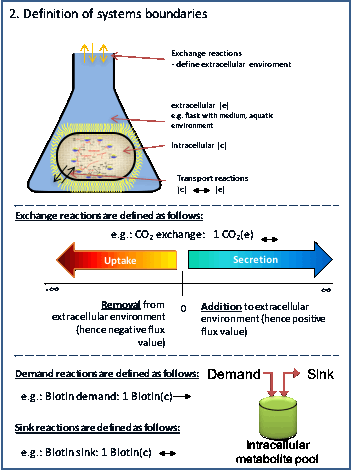

FBAsolution = optimizeCbModel (modelEcore_New,'max')

- It seems that the model can produce 3.5x mmol/gDW/h of acetate with the following constraints:

printConstraints(modelEcore_New, -1000,1000)

FBAsolution =            x: [95×1 double]
           f: 10.0000
           y: [72×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0071
           v: [95×1 double]


## ***Test if model can produce a certain ratio of two secretion products.*** 

- Let's verify that  both metabolites can be secreted independently.

modelEcoreAc = changeObjective(modelEcore,'EX_ac(e)');
FBAsolution = optimizeCbModel(modelEcoreAc,'max')

FBAsolution =            x: [95×1 double]
           f: 40
           y: [72×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0076
           v: [95×1 double]


modelEcoreFor = changeObjective(modelEcore,'EX_for(e)');
FBAsolution = optimizeCbModel(modelEcoreFor,'max')

**73. ** Add a row to the S matrix to couple the by-product secretion reactions:


modelEcore_NEW = addRatioReaction(modelEcore, {'EX_ac(e)' 'EX_for(e)'},[1 1]);


- Acetate and Formate secretion are coupled to a ratio of 1:1.

- Also, let's require that the acetate secretion flux is at least 1.

modelEcore_NEW = changeRxnBounds(modelEcore_NEW,'EX_ac(e)',1,'l');

- Optimize for growth:

modelEcore_NEW = changeObjective(modelEcore_NEW,'Biomass_Ecoli_core_w_GAM');
FBAsolution = optimizeCbModel(modelEcore_NEW,'max')

FBAsolution =            x: [95×1 double]
           f: 0.6374
           y: [73×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0071
           v: [95×1 double]


- What is the flux through the two secretion reactions:

FBAsolution.x(find(ismember(modelEcore_NEW.rxns,'EX_for(e)')))

ans = 1


FBAsolution.x(find(ismember(modelEcore_NEW.rxns,'EX_ac(e)')))

ans = 1

Keep in mind that optimizeCbModel only returns one of the possible flux distributions with maximal biomass yield.

- Note that the maximally possible biomass reaction flux decreased substantially, with these additional constraints.

- If the model shall be required to growth in addition to producing the by-product, set the lower bound of the biomass reaction to the corresponding value. We choose the value based on the FBA solution above.

modelEcore_NEW = changeRxnBounds(modelEcore_NEW, 'Biomass_Ecoli_core_w_GAM',0.6,'l');

**74.**  Change the objective function to the exchange reaction of one of your secretion product: 

modelEcore_NEW = changeObjective(modelEcore_NEW, 'EX_ac(e)');

**75.**  Maximize for the new objective function (as a secretion is expected to have a positive flux value):

FBAsolution = optimizeCbModel (modelEcore_NEW,'max')

FBAsolution =            x: [95×1 double]
           f: 1.5282
           y: [73×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0090
           v: [95×1 double]


## ***Check for blocked reactions.***

**76. ** Change simulation conditions to rich medium or open all exchange reactions:

% find exchange reactions
ExR = modelEcore.rxns(strmatch('EX_',modelEcore.rxns));
modelEcore_Open =  changeRxnBounds(modelEcore, ExR , -1000,'l');
modelEcore_Open =  changeRxnBounds(modelEcore_Open, ExR, 1000,'u');

- Verify the constraints on the model

printConstraints(modelEcore_Open,-1000,1000)

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
maxConstraints:
ATPM	8.390000e+00
ATPS4r	1.000000e+02


printUptakeBound(modelEcore_Open);

EX_ac(e)	-1000	
EX_acald(e)	-1000	
EX_akg(e)	-1000	
EX_co2(e)	-1000	
EX_etoh(e)	-1000	
EX_for(e)	-1000	
EX_fru(e)	-1000	
EX_fum(e)	-1000	
EX_glc(e)	-1000	
EX_gln_L(e)	-1000	
EX_glu_L(e)	-1000	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_lac_D(e)	-1000	
EX_mal_L(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	
EX_pyr(e)	-1000	
EX_succ(e)	-1000	


**77.**  Run analysis for blocked reactions. The function returns a list of blocked reactions (‘BlockedReactions’).

BlockedReactions = findBlockedReaction(modelEcore_Open)

BlockedReactions =     {''}


- The answer is an empty array since the* E. coli *core network has no blocked reactions. 

- If the model contains blocked reactions, please refer to the tutorial on 'gap filling' on how to proceed.

## ***Compute single gene deletion phenotypes***

**7****9.**  Gene deletion: use the following function in the COBRA Toolbox:

[grRatio,grRateKO,grRateWT, hasEffect] = singleGeneDeletion (modelEcore);

Single gene deletion analysis in progress ...

- The variable 'hasEffect'  returns whether a gene deletion has an affect on the objective function (here, growth rate). An entry of 1 in this vector means that the gene has an effect on the growth rate.

- Let's visualize hasEffect: 

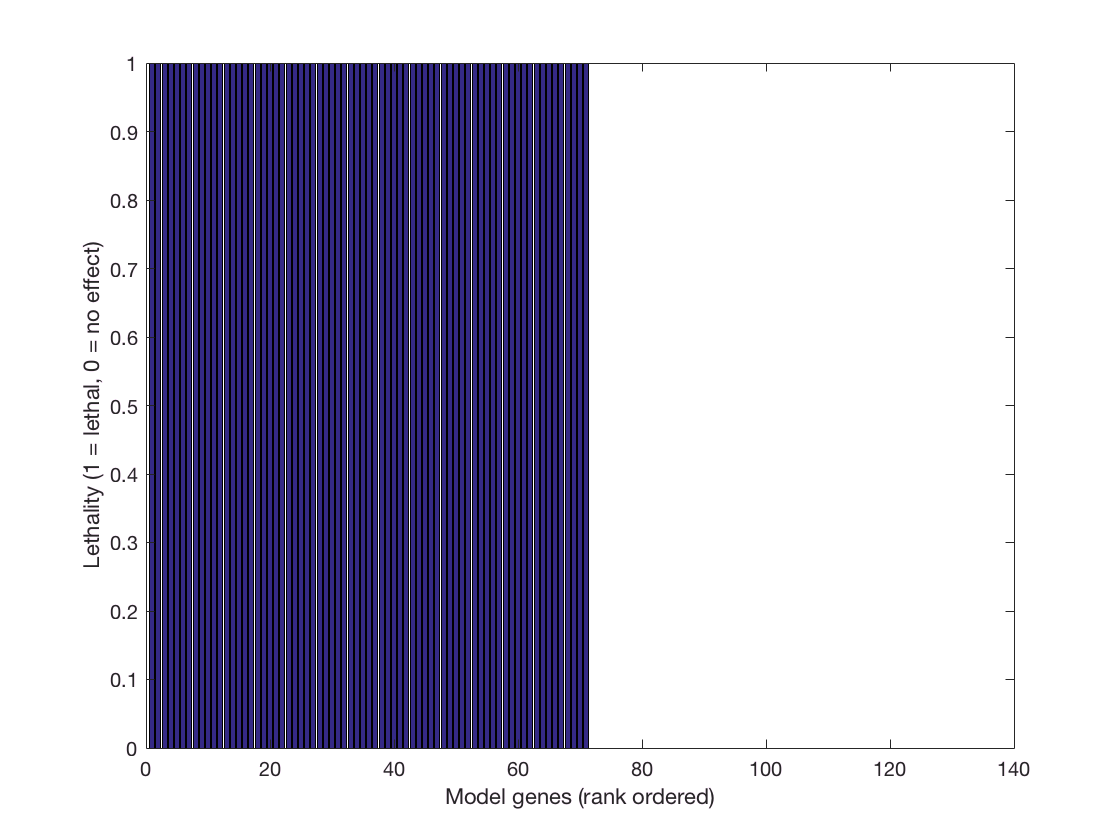

bar(sort(hasEffect,'descend'))
xlabel('Model genes (rank ordered)');
ylabel('Lethality (1 = lethal, 0 = no effect)')

- How many genes are in my model?

length(modelEcore.genes)

ans = 137

- How many genes have an effect and which ones?

length(find(hasEffect))

ans = 71

modelEcore.genes(find(hasEffect))

ans =     'b0114'
    'b0115'
    'b0116'
    'b0474'
    'b0720'
    'b0721'
    'b0722'
    'b0723'
    'b0724'
    'b0726'
    'b0727'
    'b0728'
    'b0729'
    'b0767'
    'b0809'
    'b0810'
    'b0811'
    'b1136'
    'b1479'
    'b1602'
    'b1603'
    'b1702'
    'b1761'
    'b1779'
    'b1817'
    'b1818'
    'b1819'
    'b1852'
    'b2029'
    'b2276'
    'b2277'
    'b2278'
    'b2279'
    'b2280'
    'b2281'
    'b2282'
    'b2283'
    'b2284'
    'b2285'
    'b2286'
    'b2287'
    'b2288'
    'b2415'
    'b2416'
    'b2463'
    'b2587'
    'b2779'
    'b2926'
    'b3212'
    'b3213'
    'b3236'
    'b3403'
    'b3528'
    'b3731'
    'b3732'
    'b3733'
    'b3734'
    'b3735'
    'b3736'
    'b3737'
    'b3738'
    'b3919'
    'b3956'
    'b4015'
    'b4025'
    'b4077'
    'b4151'
    'b4152'
    'b4153'
    'b4154'
    's0001'


- Which gene deletions are lethal?

- We define all growth rates lower than 0.0001 1/hr as no growth. 

tol = 1e-3;

LethalGenes = modelEcore.genes(find(grRateKO< tol))

LethalGenes =     'b0721'
    'b0722'
    'b0723'
    'b0724'
    'b1136'
    'b3919'


length(LethalGenes)

ans = 6

- Are those genes known to be lethal in the organism (in vivo)?

- Plot the effect of gene deletions on growth rate:

Some entries in 'grRateKO' maybe NaN. This is because the model is infeasible for those knockouts due to the lower bound on the 'ATPM'. We will replace those instances by zero.

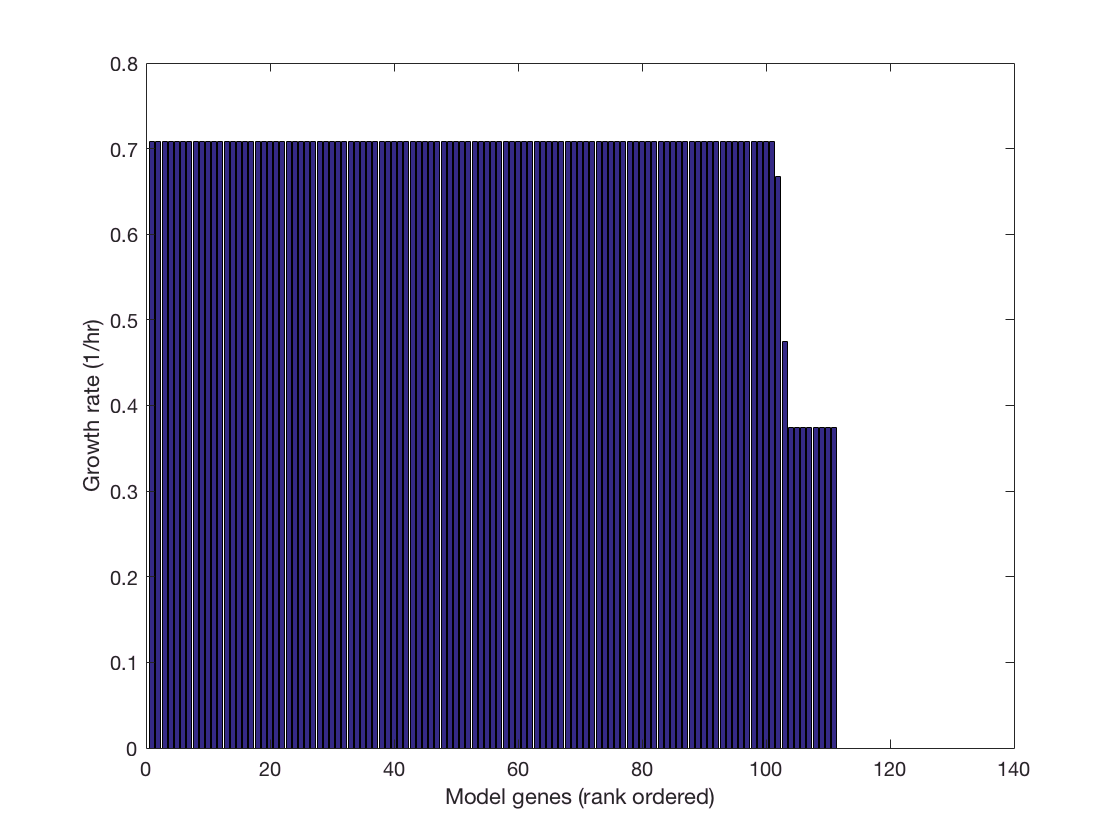

grRateKO(isnan(grRateKO)) = 0;

bar(sort(grRateKO,'descend'));
xlabel('Model genes (rank ordered)');
ylabel('Growth rate (1/hr)')

## ***Test if the model can grow fast enough. ***

**88.  **Determine reduced cost associated with network reactions when optimizing for objective function. Use

FBAsolution = optimizeCbModel(modelEcore,'max',false)

FBAsolution =            x: [95×1 double]
           f: 0.7082
           y: [72×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0386
           v: [95×1 double]


- FBAsolution.y contains the shadow price for each metabolite and FBAsolution.w contains the reduced cost for each network reaction. 

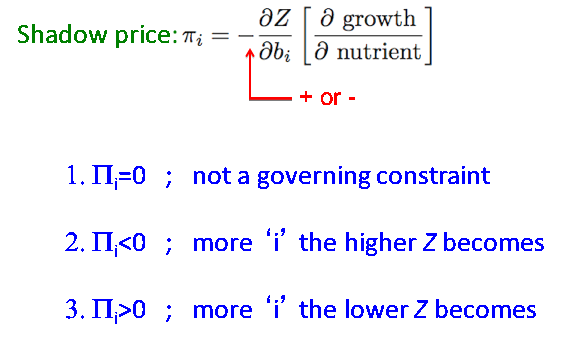

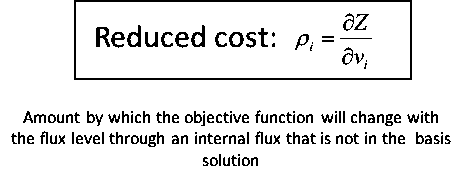

- We find the reduced cost particularly informative to identify constraints that limit the maximal value of the objective function. 

- Note that by definition the reduced cost has a negative sign. Meaning that a reaction A with a reduced cost of 35 would lead to an increase in the objective value by 35 if the flux through this reaction would be increased by 1 flux unit.

- To print those reactions that have the smallest reduced cost associated:

[a,b] = sort(FBAsolution.w,'descend');
modelEcore.rxns(b(1:10))

ans =     'EX_fru(e)'
    'EX_glc(e)'
    'ACONTb'
    'EX_ac(e)'
    'EX_acald(e)'
    'EX_etoh(e)'
    'EX_fum(e)'
    'EX_lac_D(e)'
    'EX_pyr(e)'
    'EX_succ(e)'


a(1:10)

ans =     0.1416
    0.1416
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708
    0.0708


- Generally, we are looking for exchange reactions that may be limiting the objective value (e.g., growth yield) as those ones are easy to adjust *in silico* (and *in vitro*).

- The uptake of glucose is limiting and the associated reduced cost is 0.1416, i.e., if we were to increase the flux through this reaction by 1 unit we would increase the objective by 0.1416.

- Let's test that.

- Beforehand, let's reprint the constraints again:

printConstraints(modelEcore,-1000,1000);

MinConstraints:
ACONTb	1.000000e+01
ATPM	8.390000e+00
EX_glc(e)	-1.000000e+01
maxConstraints:
ATPM	8.390000e+00
ATPS4r	1.000000e+02


printUptakeBound(modelEcore);

EX_co2(e)	-1000	
EX_glc(e)	-10	
EX_h(e)	-1000	
EX_h2o(e)	-1000	
EX_nh4(e)	-1000	
EX_o2(e)	-1000	
EX_pi(e)	-1000	


- Increase the flux through EX_glc(e) by one unit (keep in mind that uptake is defined as a negative flux through exchange reactions):

modelEcore_New = changeRxnBounds(modelEcore,'EX_glc(e)',-11,'l');
FBAsolution = optimizeCbModel(modelEcore_New,'max',false)

FBAsolution =            x: [95×1 double]
           f: 0.8499
           y: [72×1 double]
           w: [95×1 double]
        stat: 1
    origStat: 5
      solver: 'glpk'
        time: 0.0080
           v: [95×1 double]


- And indeed the biomass flux rate increased accordingly.

-  For more systematic analysis of the effect of reduced costs and limiting variable, please also refer to the tutorial on robustness and phase plane analysis.

## ***Test if the model grows too fast.***

- What are the modeling constraints?

**93.  **Single reaction deletion.

[grRatio,grRateKO,grRateWT] = singleRxnDeletion(modelEcore);

Single reaction deletion analysis in progress ...
1%      [                                        ]2%      [                                        ]3%      [.                                       ]4%      [.                                       ]5%      [..                                      ]6%      [..                                      ]7%      [..                                      ]8%      [...                                     ]9%      [...                                     ]10%     [....                                    ]11%     [....                                    ]12%     [....                                    ]13%     [.....                                   ]14%     [.....                                   ]15%     [......                                  ]16%     [......                                  ]17%     [......                                  ]18%     [.......                                 ]20%     [........                                ]

- Which gene deletion would lead to a lower growth rate?

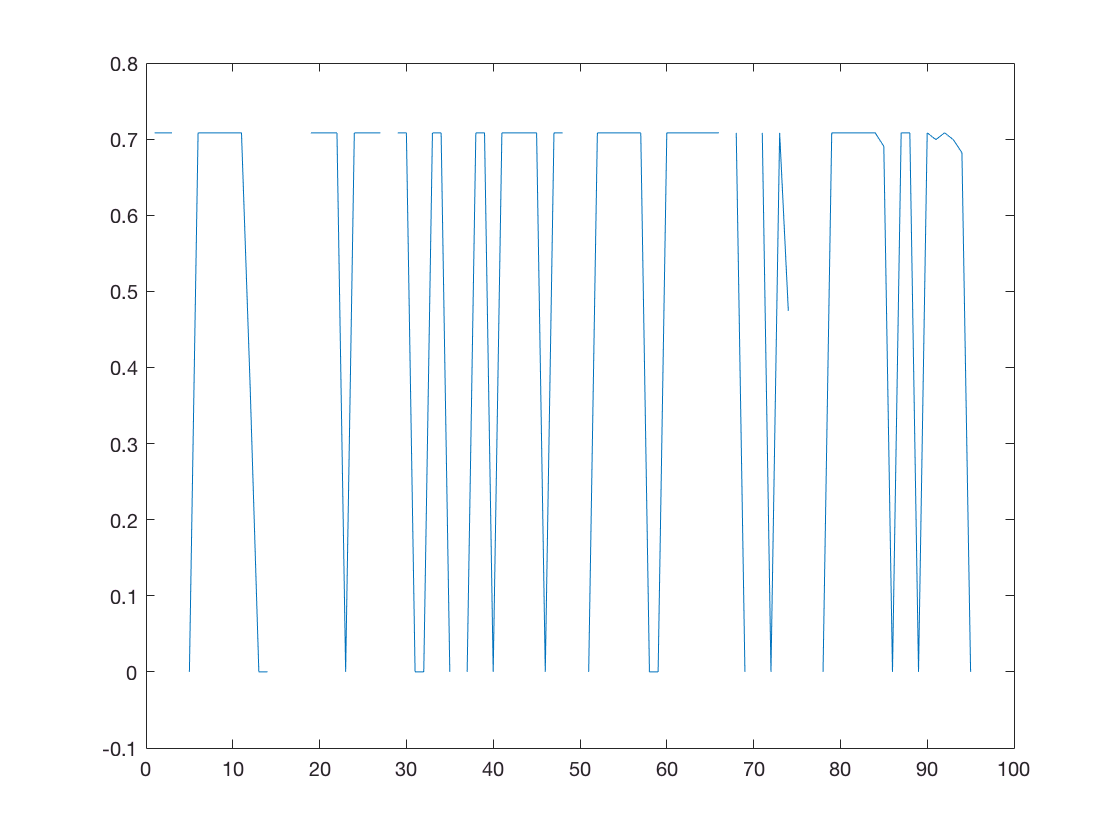

plot(grRateKO)

**94.  **Reduced cost.

See Step 89.

**95.  Print Matlab model content.  **

- Add fields if missing

if ~isfield(modelEcore, 'osense')
    modelEcore.osense = -1;
end
if ~isfield(modelEcore, 'csense')
    modelEcore.csense(1:length(modelEcore.mets),1) = 'E';
end

- Write SBML file.

writeCbModel(modelEcore,'sbml', 'EColiCore.xml')

Document written


ans =              constraint: [1×0 struct]
     functionDefinition: [1×0 struct]
                  event: [1×0 struct]
                   rule: [1×0 struct]
         unitDefinition: [1×1 struct]
      initialAssignment: [1×0 struct]
             SBML_level: 3
           SBML_version: 1
             annotation: ''
              areaUnits: ''
        avogadro_symbol: ''
       conversionFactor: ''
           delay_symbol: ''
            extentUnits: ''
    fbc_activeObjective: 'obj'
            fbc_version: 2
                     id: 'COBRAModel'
            lengthUnits: ''
                 metaid: 'COBRAModel'
                   name: ''
                  notes: ''
                sboTerm: -1
         substanceUnits: ''
              timeUnits: ''
            time_symbol: ''
               typecode: 'SBML_MODEL'
            volumeUnits: ''
                species: [1×72 struct]
            compartment: [1×2 struct]
              parameter: [1×7 struct]
               reaction: [1×95 st

## TIMING

The tutorial runs as given in a few seconds to minutes. 

However, if you use this tutorial for debugging and generating your own model, please consider the timing of the steps, as they had been given in the original SOP [1].

The timing of the entire reconstruction process depends on the properties of the target organism (prokaryote vs. eukaryote, genome size), the quality of the genome annotation, and the availability of experimental data. The timing listed below represents an average and can be used to plan the different stages. 

Step 1. through 4, (Stage 1, draft reconstruction): days to a week.

Step 5. (Stage 1, collection of experimental data): ongoing throughout the reconstruction process

Step 6. through 23. (Stage 2, reconstruction refinement): months to a year (if debugging and gap filling is done along the way)

Step 24. through 32.     (Stage 2, biomass determination): days to weeks, depending on data availability 

Step 34. through 36|.     (Stage 2, biomass determination): days to a week. 

Step 37. (Stage 2, growth requirements): days to weeks, depending on data availability 

Step 38. through 42. (Stage 3, conversion): days to a week.

Step 43. through 94. (Stage 4, network evaluation/debugging): week to months.

Step 95. and 96. (Data assembly): days to weeks, depending how much and in which format data was collected.

## **TROUBLESHOOTING**

Taken from [1].

Step 38,                 See installation instructions of the COBRA Toolbox for details on how to install and setup Matlab, SBML and COBRA Toolbox.

Step 51.                 Make sure that you are working in the directory were the X3.exe script was copied to. The .expa file produced by the function must be in the same directory as X3.exe. 

## **ANTICIPATED RESULTS**

Taken from [1].

This protocol will result in a reconstruction that covers most of the known metabolic information of the target organism and represents a knowledge database. This reconstruction can be used as a resource for information (query tool), high-throughput data mapping (context for content), and a starting point for mathematical models. 

## References

[1] Thiele Nat Protoc

[2] EcoSal

[3] iAF1260

*Geobacter** sulfurreducans [4]*